# Compare Airspeed

## **Load WR data**

%load('../data/dc_corr')
ii_d = [6 28 8];% deflg, demem, frmtc

## Load Insec/Bird Birdscan

load('BS/Sempach_2018_combined')
BS.air=BS.flight-BS.wind;

add value of BS location.

lat = 47.128054;
lon = 8.192377;
alt = 540;

Add seasonal variables

t=datetime('2018-01-01'):datetime('2019-01-01');
season = datetime([737121 737184 737273 737384 737121+365],'ConvertFrom','datenum');
season_label = {'Spring (02-Mar  - 04-May)','Summer (4-May - 1-Aug)','Autumn (1-Aug - 20-Nov)','Winter (20-Nov - 02-Mar)'};
BS.season = sum(bsxfun(@gt, datenum(BS.time_string), datenum(season)),2);

Add day assocaite

[~,BS.day_id] = ismember(dateshift(BS.time_string,'start','day'),t);

Define parameter of histogram

norm = 'pdf';
edge_angle=16;
edge_hist = 0:30;

## Filter BS data

Define the thresholds of the filters

minprobinsect=.7;
minprobbird=.3;
maxalt = 500;
minalt = 50;

Apply filter

BSs = BS(BS.altitude>minalt & BS.altitude<maxalt & (BS.predicted_class_prob>minprobinsect|BS.isBird) & (BS.predicted_class_prob>minprobbird|~BS.isBird) & ~isnan(BS.flight),:);

Description of the data before and after filtering

fprintf(['Number of insect track: ' num2str(sum(~BS.isBird)) ' (nan: ' num2str(mean(isnan(BS.flight(~BS.isBird)))*100,2) 'perc.) \nNumber of bird track: ' num2str(sum(BS.isBird)) ' (nan: ' num2str(mean(isnan(BS.flight(BS.isBird)))*100,2) 'perc)'])

Number of insect track: 626006 (nan: 62perc.) 
Number of bird track: 234199 (nan: 59perc)

disp(['Filter kept ' num2str(round(size(BSs,1)/size(BS,1)*100)) '% of the data'])

Filter kept 30% of the data


fprintf(['Number of insect track: ' num2str(sum(~BSs.isBird)) ' \nNumber of bird track: ' num2str(sum(BSs.isBird)) ])

Number of insect track: 213751 
Number of bird track: 43763

Illustration: Probability

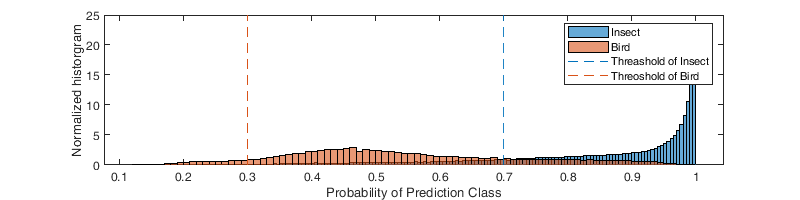

col = get(gca,'ColorOrder');
figure('position',[0 0 800 200]); hold on;
p1=histogram(BS.predicted_class_prob(~BS.isBird),'Normalization',norm);
p2=histogram(BS.predicted_class_prob(BS.isBird),'Normalization',norm);
plot([minprobinsect minprobinsect],[0 25],'--','Color',col(1,:))
plot([minprobbird minprobbird],[0 25],'--','Color',col(2,:));
xlabel('Probability of Prediction Class'); ylabel('Normalized historgram'); box on;
legend({'Insect','Bird','Threashold of Insect','Threoshold of Bird'})

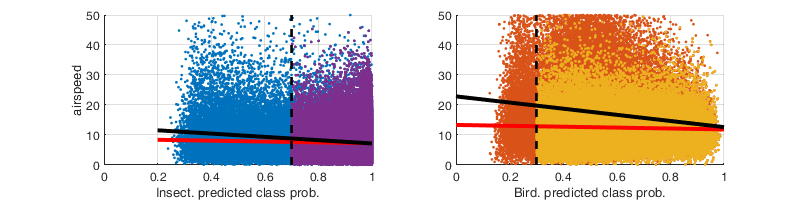

figure('position',[0 0 800 200]);
subplot(1,2,1); hold on; 
plot(BS.predicted_class_prob(~BS.isBird),abs(BS.air(~BS.isBird)),'.');
plot(BSs.predicted_class_prob(~BSs.isBird),abs(BSs.air(~BSs.isBird)),'.','Color',col(4,:));
h=lsline; h(1).LineWidth = 3; h(1).Color='r'; h(2).LineWidth = 3; h(2).Color='k';
plot([minprobinsect minprobinsect],[0 50],'--k','LineWidth',2)
axis([0 1 0 50 ]); grid on; ylabel('airspeed'); xlabel('Insect. predicted class prob.')
subplot(1,2,2); hold on;
set(gca,'ColorOrderIndex',2)
plot(BS.predicted_class_prob(BS.isBird),abs(BS.air(BS.isBird)),'.','Color',col(2,:));
plot(BSs.predicted_class_prob(BSs.isBird),abs(BSs.air(BSs.isBird)),'.','Color',col(3,:));
h=lsline; h(1).LineWidth = 3; h(1).Color='r'; h(2).LineWidth = 3; h(2).Color='k';
plot([minprobbird minprobbird],[0 50],'--k','LineWidth',2);
axis([0 1 0 50 ]); grid on;  xlabel('Bird. predicted class prob.')

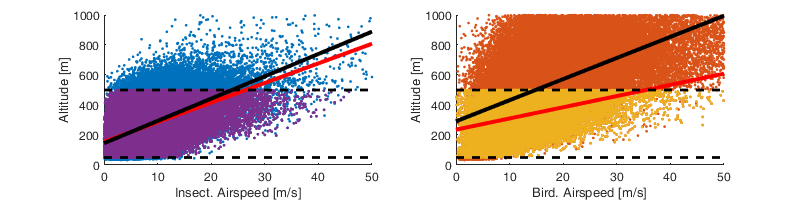

figure('position',[0 0 800 200]); hold on; 
subplot(1,2,1); hold on;
plot(abs(BS.air(~BS.isBird)),BS.altitude(~BS.isBird),'.');
plot(abs(BSs.air(~BSs.isBird)),BSs.altitude(~BSs.isBird),'.','Color',col(4,:));
h=lsline; h(1).LineWidth = 3; h(1).Color='r'; h(2).LineWidth = 3; h(2).Color='k';
axis([0 50 0 1000]); xlabel('Insect. Airspeed [m/s]'); ylabel('Altitude [m]')
plot([0 50],[minalt minalt],'--k','LineWidth',2);
plot([0 50],[maxalt maxalt],'--k','LineWidth',2);
subplot(1,2,2); hold on;
plot(abs(BS.air(BS.isBird)),BS.altitude(BS.isBird),'.','Color',col(2,:));
plot(abs(BSs.air(BSs.isBird)),BSs.altitude(BSs.isBird),'.','Color',col(3,:));
h=lsline; h(1).LineWidth = 3; h(1).Color='r'; h(2).LineWidth = 3; h(2).Color='k';
plot([0 50],[minalt minalt],'--k','LineWidth',2);
plot([0 50],[maxalt maxalt],'--k','LineWidth',2);
axis([0 50 0 1000]); xlabel('Bird. Airspeed [m/s]'); ylabel('Altitude [m]')

Description of the speed

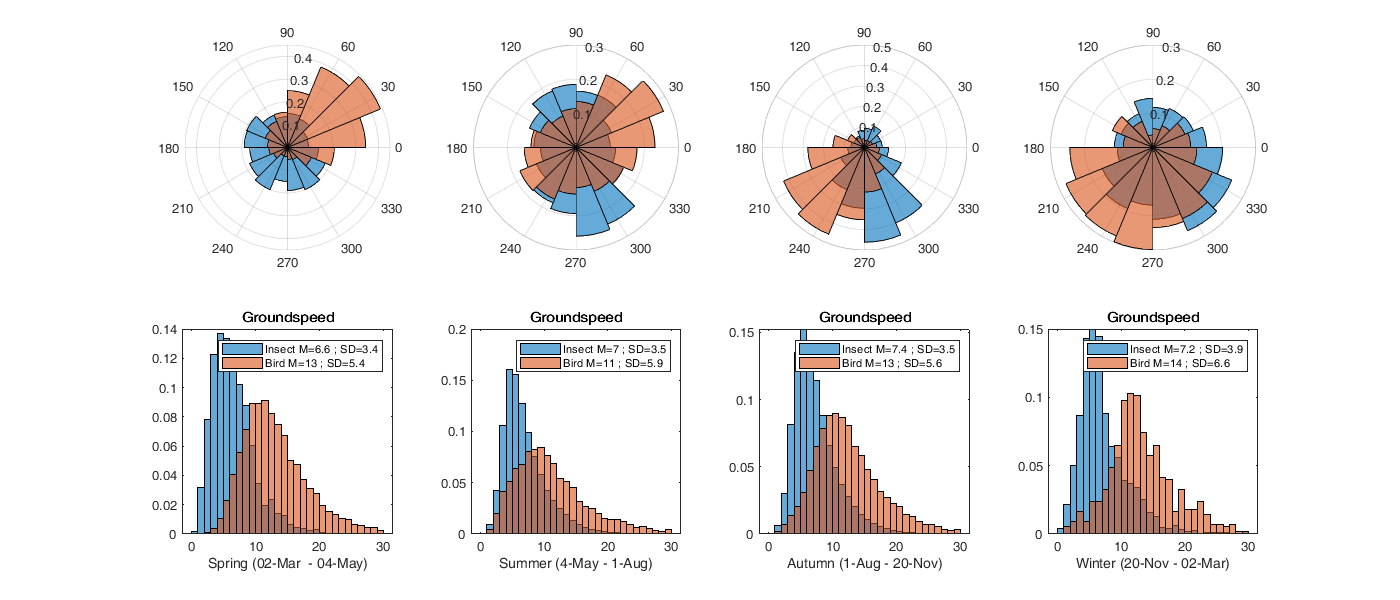

figure('position',[0 0 1400 600])
for i_s=1:4
    subplot(2,4,i_s)
    polarhistogram(angle(BSs.flight(~BSs.isBird & BSs.season==i_s)),edge_angle,'Normalization',norm); hold on;
    polarhistogram(angle(BSs.flight(BSs.isBird & BSs.season==i_s)),edge_angle,'Normalization',norm);
    subplot(2,4,4+i_s)
    histogram(abs(BSs.flight(~BSs.isBird & BSs.season==i_s)),edge_hist,'Normalization',norm); hold on;
    histogram(abs(BSs.flight(BSs.isBird & BSs.season==i_s)),edge_hist,'Normalization',norm);
    xlabel(season_label{i_s})
    legend({['Insect M=' num2str(mean(abs(BSs.flight(~BSs.isBird & BSs.season==i_s))),2) ' ; SD=' num2str(std(abs(BSs.flight(~BSs.isBird & BSs.season==i_s))),2)],...
        ['Bird M=' num2str(mean(abs(BSs.flight(BSs.isBird & BSs.season==i_s))),2) ' ; SD=' num2str(std(abs(BSs.flight(BSs.isBird & BSs.season==i_s))),2)]})
    title('Groundspeed');
end

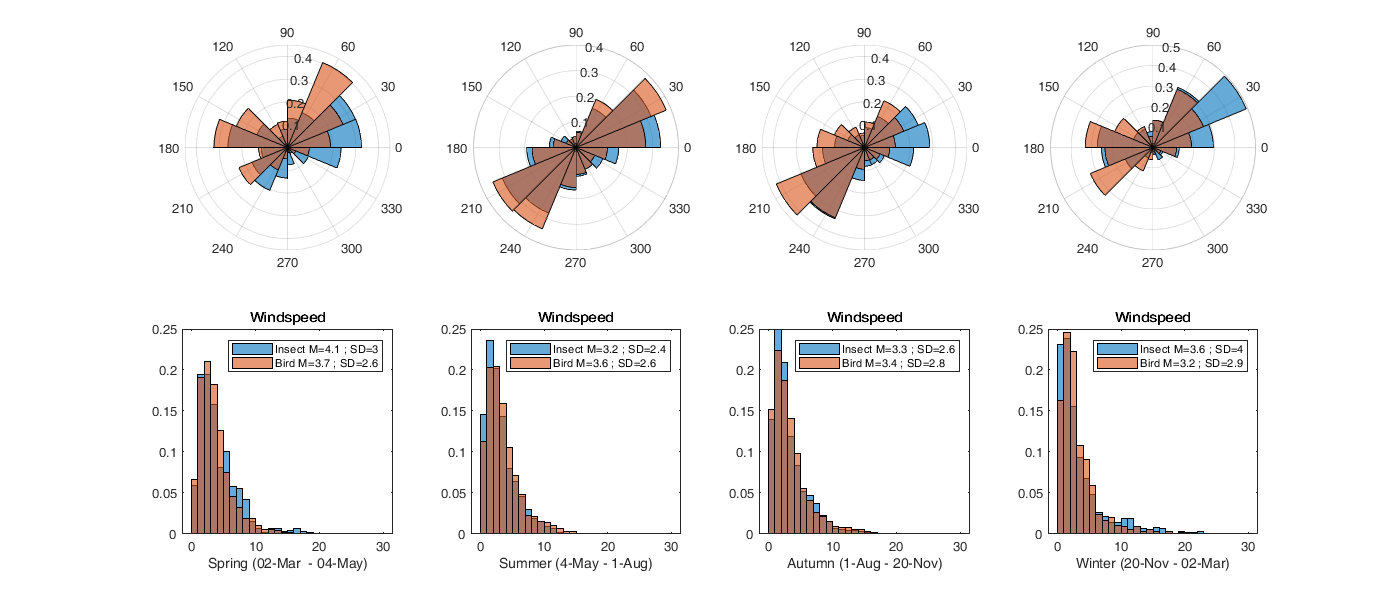

figure('position',[0 0 1400 600])
for i_s=1:4
    subplot(2,4,i_s)
    polarhistogram(angle(BSs.wind(~BSs.isBird & BSs.season==i_s)),edge_angle,'Normalization',norm); hold on;
    polarhistogram(angle(BSs.wind(BSs.isBird & BSs.season==i_s)),edge_angle,'Normalization',norm);
    subplot(2,4,4+i_s)
    histogram(abs(BSs.wind(~BSs.isBird & BSs.season==i_s)),edge_hist,'Normalization',norm); hold on;
    histogram(abs(BSs.wind(BSs.isBird & BSs.season==i_s)),edge_hist,'Normalization',norm);
    xlabel(season_label{i_s})
    legend({['Insect M=' num2str(mean(abs(BSs.wind(~BSs.isBird & BSs.season==i_s))),2) ' ; SD=' num2str(std(abs(BSs.wind(~BSs.isBird & BSs.season==i_s))),2)],...
        ['Bird M=' num2str(mean(abs(BSs.wind(BSs.isBird & BSs.season==i_s))),2) ' ; SD=' num2str(std(abs(BSs.wind(BSs.isBird & BSs.season==i_s))),2)]})
    title('Windspeed');
end

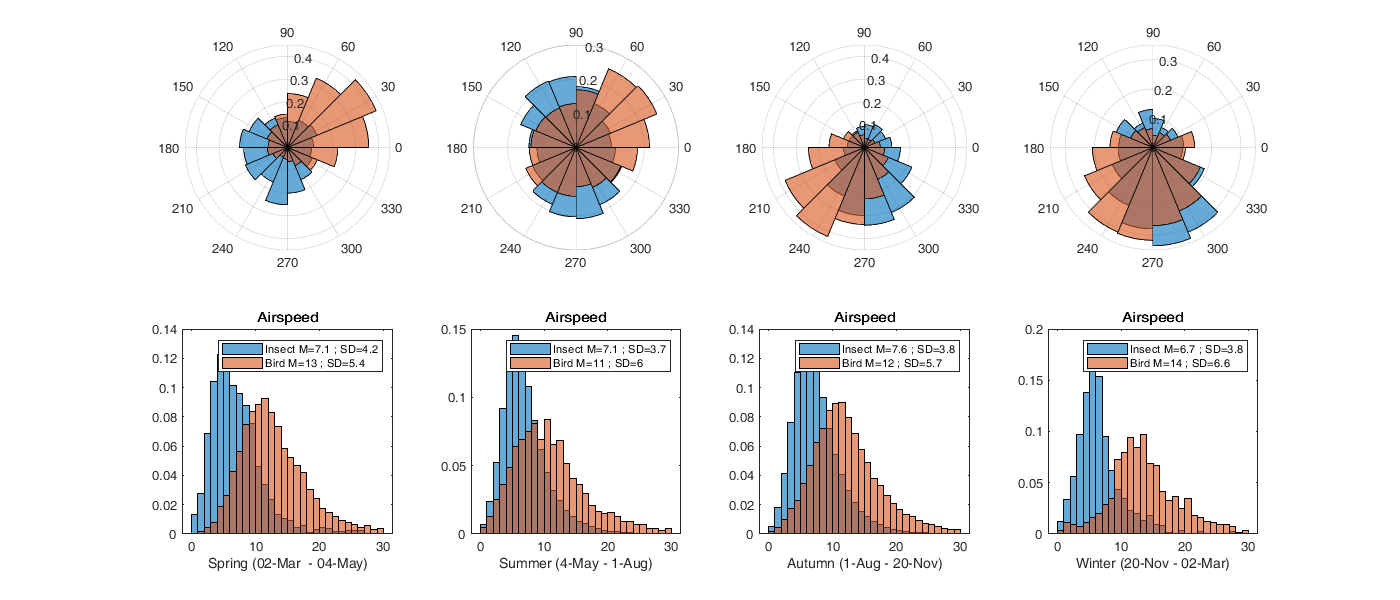

figure('position',[0 0 1400 600])
for i_s=1:4
    subplot(2,4,i_s)
    polarhistogram(angle(BSs.air(~BSs.isBird & BSs.season==i_s)),edge_angle,'Normalization',norm); hold on;
    polarhistogram(angle(BSs.air(BSs.isBird & BSs.season==i_s)),edge_angle,'Normalization',norm);
    subplot(2,4,4+i_s)
    histogram(abs(BSs.air(~BSs.isBird & BSs.season==i_s)),edge_hist,'Normalization',norm); hold on;
    histogram(abs(BSs.air(BSs.isBird & BSs.season==i_s)),edge_hist,'Normalization',norm);
    xlabel(season_label{i_s})
    legend({['Insect M=' num2str(mean(abs(BSs.air(~BSs.isBird & BSs.season==i_s))),2) ' ; SD=' num2str(std(abs(BSs.air(~BSs.isBird & BSs.season==i_s))),2)],...
        ['Bird M=' num2str(mean(abs(BSs.air(BSs.isBird & BSs.season==i_s))),2) ' ; SD=' num2str(std(abs(BSs.air(BSs.isBird & BSs.season==i_s))),2)]})
    title('Airspeed');
end

## Nighly average

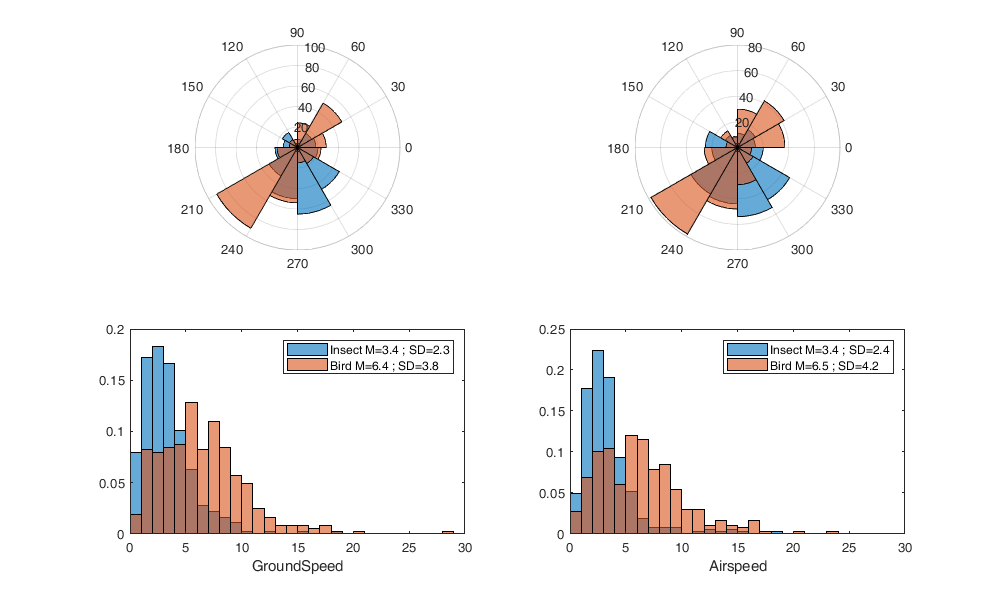

bird_flight = nan(1,numel(t)); bird_air = nan(1,numel(t));
insect_flight = nan(1,numel(t)); insect_air = nan(1,numel(t));

[G,ID] = findgroups(BSs.day_id(BSs.isBird));
bird_flight(ID) = splitapply(@mean, BSs.flight(BSs.isBird), G);
bird_air(ID) = splitapply(@mean, BSs.air(BSs.isBird), G);

[G,ID] = findgroups(BSs.day_id(~BSs.isBird));
insect_flight(ID) = splitapply(@mean, BSs.flight(~BSs.isBird), G);
insect_air(ID) = splitapply(@mean, BSs.air(~BSs.isBird), G);

figure('position',[0 0 1000 600])
subplot(2,2,1)
polarhistogram(angle(insect_flight),12); hold on;
polarhistogram(angle(bird_flight),12)
subplot(2,2,2)
polarhistogram(angle(insect_air),12); hold on;
polarhistogram(angle(bird_air),12);
subplot(2,2,3)
histogram(abs(insect_flight),0:30,'Normalization',norm); hold on;
histogram(abs(bird_flight),0:30,'Normalization',norm);
legend({['Insect M=' num2str(round(nanmean(abs(insect_flight)),1)) ' ; SD=' num2str(round(nanstd(abs(insect_flight)),1)) ],['Bird M=' num2str(round(nanmean(abs(bird_flight)),1)) ' ; SD=' num2str(round(nanstd(abs(bird_flight)),1)) ]})
xlabel('GroundSpeed'); xlim([0 30])
subplot(2,2,4)
histogram(abs(insect_air),0:1:30,'Normalization',norm); hold on;
histogram(abs(bird_air),0:1:30,'Normalization',norm);
legend({['Insect M=' num2str(round(nanmean(abs(insect_air)),1)) ' ; SD=' num2str(round(nanstd(abs(insect_air)),1)) ],['Bird M=' num2str(round(nanmean(abs(bird_air)),1)) ' ; SD=' num2str(round(nanstd(abs(bird_air)),1)) ]})
xlabel('Airspeed'); xlim([0 30])

## Averaging produced by WR

Roughly accounting for volume size difference with WR

Radius of weather radar (WR) and birdscan (BS). We compute the average beam width from the beam angle and the height used

rWR = 25;
baBS = 17.5;% beam angle deg
rBS = @(h) h*tand(baBS);

Volume covered by WR (no coverage within first 5km

VWR = rWR^2*pi-5^2*pi

VWR = 1.8850e+03

VBS = rBS(maxalt/1000)^2*pi*maxalt/1000/3 - rBS(minalt/1000)^2*pi*minalt/1000/3

VBS = 0.0130

The duration can be found from speed.

dtBS = @(v) (VWR - VBS) / (2*rBS((maxalt+minalt)/2/1000)*v);

Assume a initial bird speed of 10 m/s -> 864 km/day

dtBS(10/1000*60*60*24)

ans = 12.5805

dtBS(20/1000*60*60*24)

ans = 6.2903

This would require to do average over 10+ days. NOT POSSIBLE

Attempt to upscale the distribution

Qin=nan(2,numel(t),4);
Qan=nan(2,numel(t),4);
for i_t=1:numel(t)
    for i_isBird=0:1
        tmp=BSs.flight(BSs.day_id==i_t & BSs.isBird==i_isBird);
        if (size(tmp,1))>50 % minimum number of tracks to consider the night
            Qin(i_isBird+1,i_t,1)=mean(abs(tmp));
            Qin(i_isBird+1,i_t,2)=quantile(abs(tmp),.1);
            Qin(i_isBird+1,i_t,3)=quantile(abs(tmp),.9);
            Qin(i_isBird+1,i_t,4)=std(tmp);
            
            nb_day = dtBS(mean(abs(tmp))/1000*60*60*24);
            
            [f,xi] = ksdensity([real(tmp) imag(tmp)]);
            
            xiid = datasample(1:numel(f),round(nb_day*size(tmp,1)),'weight',f);
            
            SimSam = xi(xiid,1) + xi(xiid,2)*1i;
            Qan(i_isBird+1,i_t,1)=abs(mean(SimSam));
            Qan(i_isBird+1,i_t,2)=abs(quantile(SimSam,0.1));
            Qan(i_isBird+1,i_t,3)=abs(quantile(SimSam,0.9));
            Qan(i_isBird+1,i_t,4)=std(SimSam);
        end
    end
end

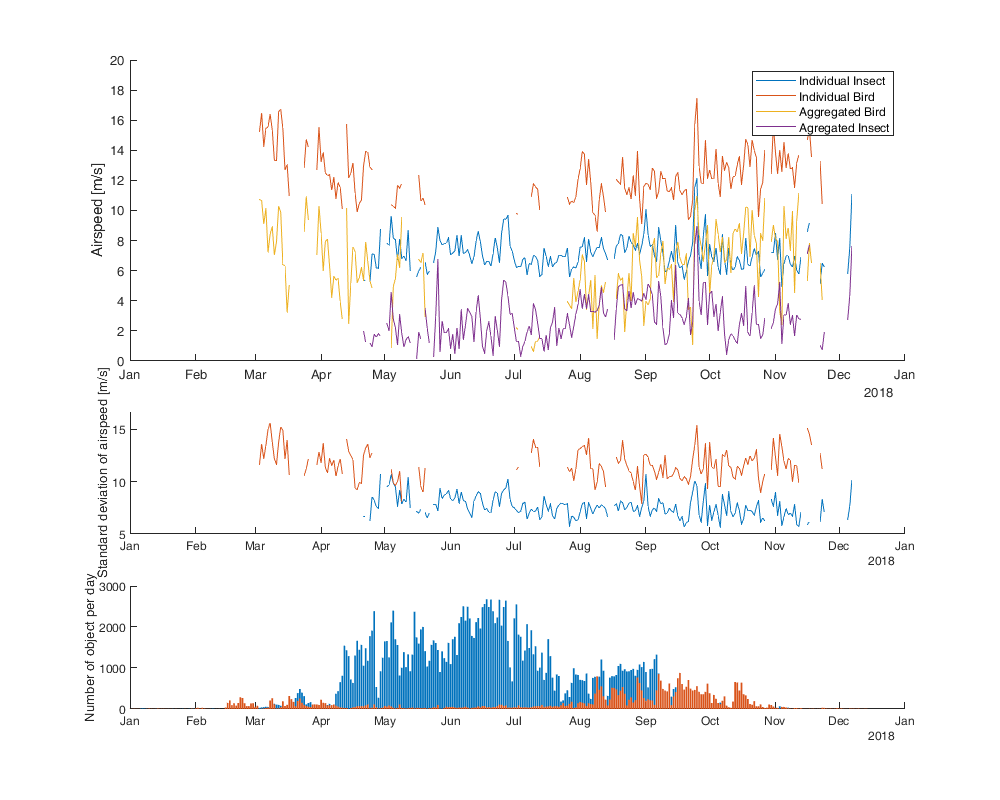

figure('position',[0 0 1000 800]); 
subplot(4,1,[1 2]);hold on;
%plot(t,Y)
%legend({'Mean of flight speed over day', 'Speed of flight mean over day', 'Mean of flight speed for volume', 'Speed of flight mean for volume'})

idt=~any(isnan(Qin(:,:,1)));
%fill([t(idt), fliplr(t(idt))], [Y(1,idt,2), fliplr(Y(1,idt,3))],'b','FaceAlpha',.2,'EdgeColor','none')
%fill([t(idt), fliplr(t(idt))], [Y(4,idt,2), fliplr(Y(4,idt,3))],'r','FaceAlpha',.2,'EdgeColor','none')
plot(t,Qin(1,:,1)); 
plot(t,Qin(2,:,1)); 
plot(t,Qan(2,:,1)); 
plot(t,Qan(1,:,1)); 
legend({'Individual Insect','Individual Bird','Aggregated Bird','Agregated Insect'})
ylim([0 20]); xlim([t(1) t(end)]); ylabel('Airspeed [m/s]')
subplot(4,1,3); hold on; 
plot(t,Qan(1,:,4))
plot(t,Qin(2,:,4))
xlim([t(1) t(end)]);  ylabel('Standard deviation of airspeed [m/s]')
subplot(4,1,4); hold on;
bar(t,histcounts(findgroups(BSs.day_id(~BSs.isBird)),0.5:1:numel(t)+0.5))
bar(t,histcounts(findgroups(BSs.day_id(BSs.isBird)),0.5:1:numel(t)+0.5))
xlim([t(1) t(end)]); ylabel('Number of object per day')

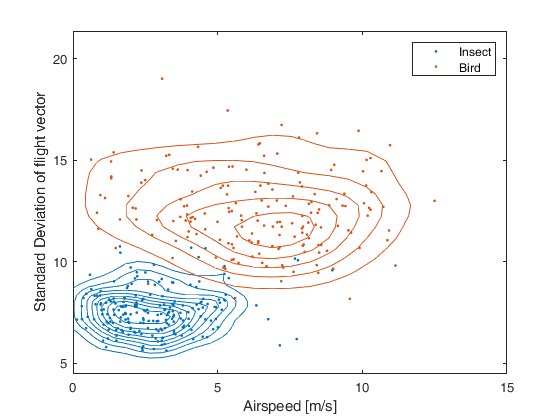

figure; hold on;
scatter(Qan(1,:,1),Qan(1,:,4),'.')
scatter(Qan(2,:,1),Qan(2,:,4),'.')
[f,xi] = ksdensity([Qan(1,:,1)' Qan(1,:,4)']);
f = reshape(f,sqrt(numel(f)),[]);
contour(unique(xi(:,1)),unique(xi(:,2)),f,'Color',col(1,:))
[f,xi] = ksdensity([Qan(2,:,1)' Qan(2,:,4)']);
f = reshape(f,sqrt(numel(f)),[]);
contour(unique(xi(:,1)),unique(xi(:,2)),f,'Color',col(2,:));
box on; legend({'Insect','Bird'});
xlabel('Airspeed [m/s]'); ylabel('Standard Deviation of flight vector');
xlim([0 15])